# Gibbs Effect

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the square wave signal $\tilde{x}(t)$ shown below:

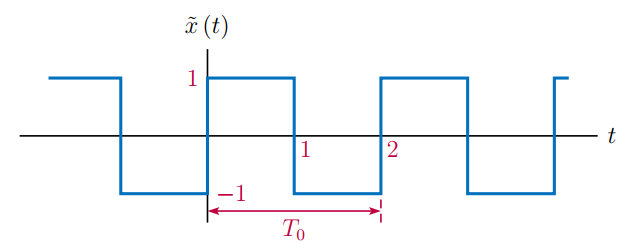

TFS coefficcients for $\tilde{x}(t)$ are

$a_{k}=0$   and   $b_{k}=\left\{\begin{array}{c l}
\frac{4}{\pi k}, & k\;\textrm{odd}\\
0, & k\;\textrm{even}
\end{array}\right.$

Finite harmonic approximation to $\tilde{x}(t)$ using $m$ harmonics is


$$\tilde{x}^{(m)}\left(t\right) =
\sum_{\underset{\scriptstyle{k\;\textrm{odd}}}{k=1}}^{m}
\left(\frac{4}{\pi k}\right)\,
\sin\left(k \pi t\right)$$


Approximation error when using $m$ harmonics is


$$\tilde{\varepsilon}^{(m)}\left(t\right) =
\tilde{x}\left(t\right) - \tilde{x}^{(m)}\left(t\right)$$


k = [1:21];  % Vector of indices
% Compute EFS coefficients
bk = zeros(1,21);
k_odd = [1:2:21];
bk(k_odd) = 4./(pi*k_odd);
t = [-0.25:0.001:2.25];  % Vector of time instants
x = square(2*pi*0.5*t);

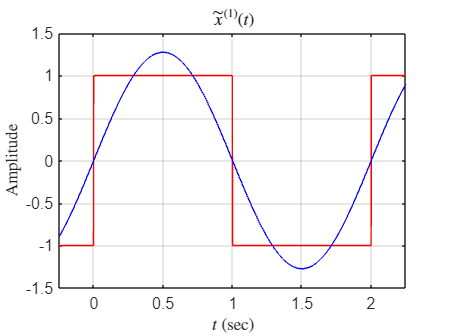

% Graph approximation and error for m=1
xtilde1 = approx(1,bk,t);
plot(t,x,'r-',t,xtilde1,'b-'); grid;
axis([-0.25,2.25,-1.5,1.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{x}^{(1)}(t)$');

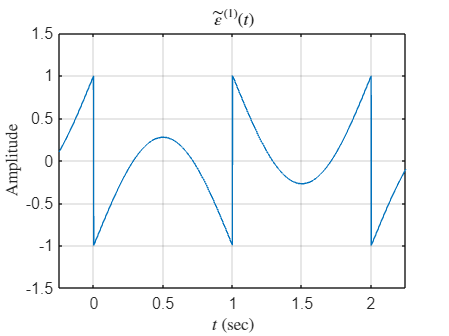

plot(t,xtilde1-x); grid;
axis([-0.25,2.25,-1.5,1.5]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{\varepsilon}^{(1)}(t)$');

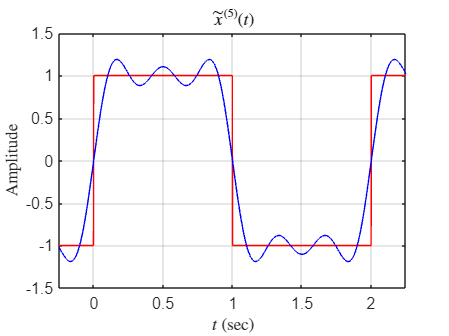

% Graph approximation and error for m=5
xtilde5 = approx(5,bk,t);
plot(t,x,'r-',t,xtilde5,'b-'); grid;
axis([-0.25,2.25,-1.5,1.5]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{x}^{(5)}(t)$');

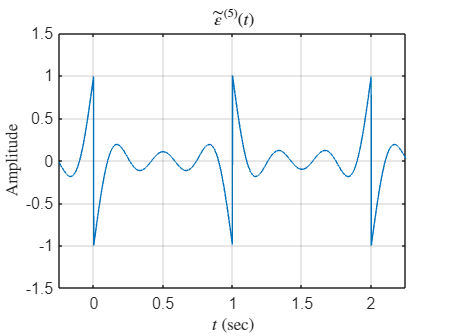

plot(t,xtilde5-x); grid;
axis([-0.25,2.25,-1.5,1.5]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{\varepsilon}^{(5)}(t)$');

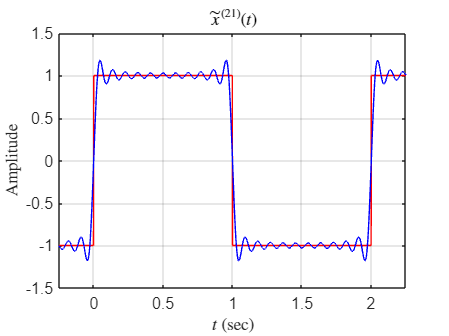

% Graph approximation and error for m=21
xtilde21 = approx(21,bk,t);
plot(t,x,'r-',t,xtilde21,'b-'); grid;
axis([-0.25,2.25,-1.5,1.5]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{x}^{(21)}(t)$');

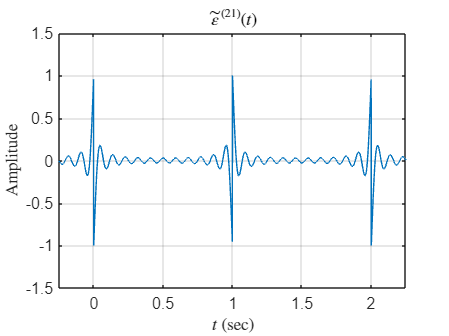

eps21 = xtilde21-x;
plot(t,eps21); grid;
axis([-0.25,2.25,-1.5,1.5]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{\varepsilon}^{(21)}(t)$');

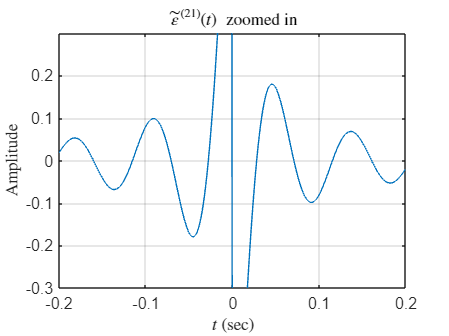

plot(t(51:450),eps21(51:450)); grid;
axis([-0.2,0.2,-0.3,0.3]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$\tilde{\varepsilon}^{(21)}(t)\;$ zoomed in');

set(0,'defaultTextInterpreter','tex');

Local function to compute the finite-harmonic approximation.

function xtilde = approx(m,bk,t)
  xtilde = zeros(size(t));
  for k = 1:m
    xtilde = xtilde+bk(k)*sin(2*pi*k*0.5*t);
  end
end